### Load

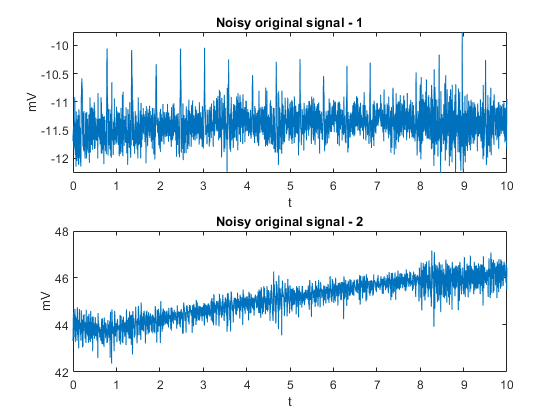

clear; clc; close all;
noisySignal = load('data\Emma\EMG\Emma_EMG_FullFlex_Leads.csv');
cleanSignal = load('data\Emma\EMG\Emma_EMG_Relaxed_Leads.csv');

fs = 512; % Sampling rate
N=length(noisySignal); 
t=0:1/fs:(N-1)/fs; % time line for plotting

% Plot the original signals
multiPlot(t, noisySignal, 'Noisy original signal', 't', 'mV')

multiPlot(t, cleanSignal, 'Clean original signal', 't', 'mV')

### Preprocess

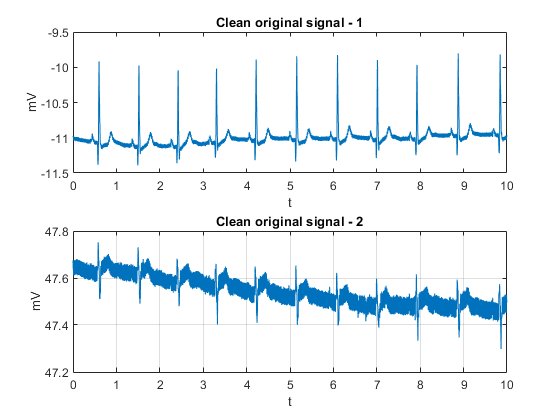

noisySignal = preprocess(noisySignal, fs, t);
cleanSignal = preprocess(cleanSignal, fs, t);

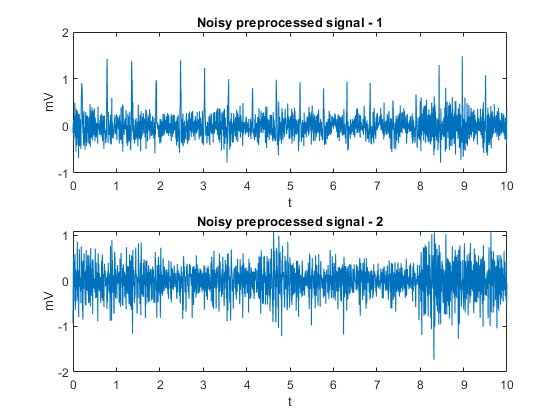


% Plot the preprocessed signals
multiPlot(t, noisySignal, 'Noisy preprocessed signal', 't', 'mV')

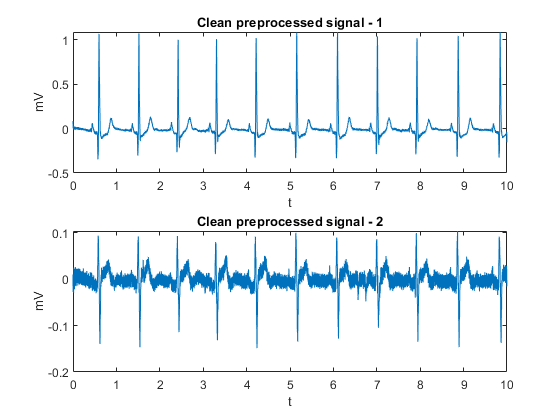

multiPlot(t, cleanSignal, 'Clean preprocessed signal', 't', 'mV')

### ICA test

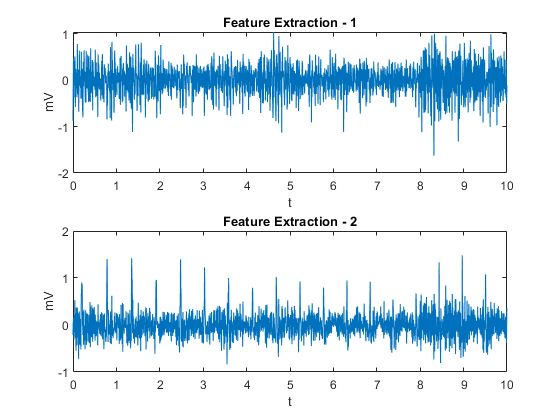

q = 2; % Amount of features to be extracted
model = rica(noisySignal, q);
features = transform(model, noisySignal);

multiPlot(t, features, 'Feature Extraction', 't', 'mV')

### SVD test

[U, S, V] = svd(features);
Srec = S

Srec =    21.8533         0
         0   16.1852
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


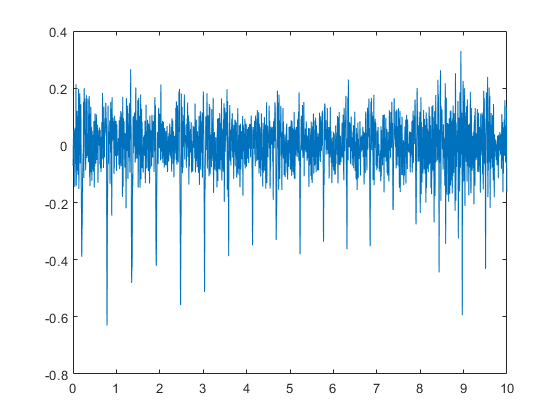

 Srec(1,1) = 0;
% Srec(3,3) = 0;

Yrec = U*Srec*V';
figure
plot(t,Yrec(:,1))

% figure
% plot(Yrec(:,2))

### Frequency Spectrum

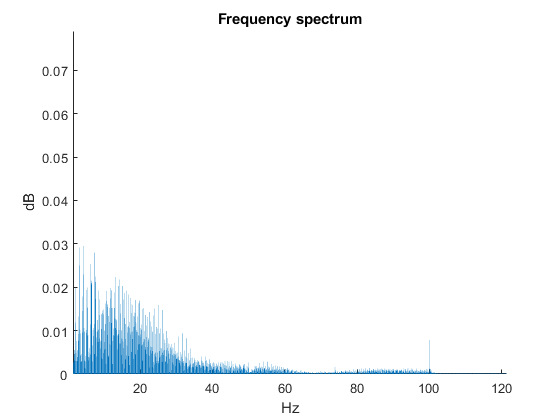

X = fft(cleanSignal);
p2 = abs(X)/N;
p1 = p2(1:N/2+1);
p1(2:end-1) = 2*p1(2:end-1);
f = fs*(0:(N/2))/N; %linspace(0,fs/2, L/2+1)

%unfiltered freq
figure
%subplot(2,1,1); 
hold on;
bar(f, p1);
title('Frequency spectrum')
xlabel('Hz')
ylabel('dB')
ylim([0 0.08])
xlim([0 120])